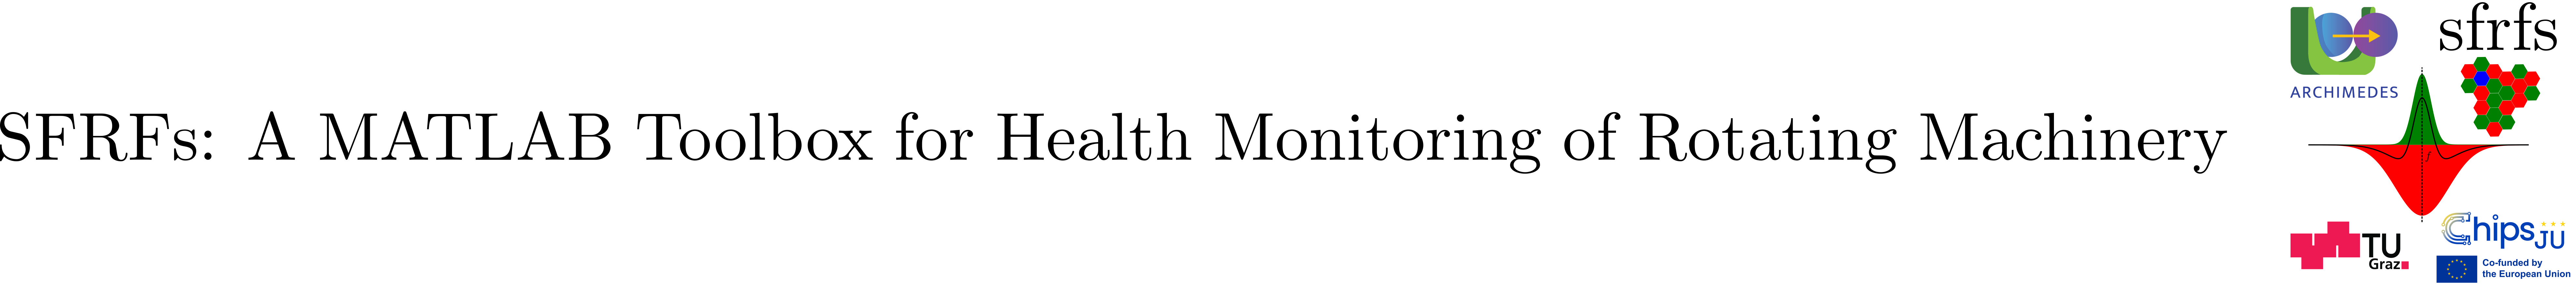

# ContrastPolarityChannelDatasetBuilder

**(Builds harmonic contrast and event-channel datasets for bearing prognosis)**

## Summary

`ContrastPolarityChannelDatasetBuilder` is a handle class that constructs structured harmonic contrast and event-channel datasets from bearing-run spectral observations. It integrates lifted harmonic receptive-field responses, sensor-local center-surround contrast, cross-sensor polarity agreement filtering, and temporal polarity event detection into a unified representation for bearing prognosis.

**Key features:**

- Processes individual bearing runs or complete data ensembles.

- Supports multiple monitored fault-frequency families, each with its own lifted harmonic gain functions.

- Computes contrast independently for two spectral sensor channels.

- Resolves cross-sensor contrast using an asymmetrically updated agreement floor.

- Detects polarity reversals and positive and negative ON/OFF activity transitions.

- Preserves raw sensor-local contrasts, agreement-floor histories, resolved contrasts, and event channels.

- Produces structured tables with one row per bearing run and monitored fault family.

- Retains observation-by-harmonic matrices without global padding, accommodating different run lengths and harmonic counts.

- Propagates operating conditions, lifetime information, and bearing failure indicators into the resulting dataset.

The class integrates the contrast-polarity operators underlying the bearing degradation monitoring framework described in [3].

## Description

`ContrastPolarityChannelDatasetBuilder` assembles harmonic-indexed prognosis-channel datasets by applying a sequence of spectral response, contrast, agreement-filtering, and polarity-event operations to bearing-run observations.

The builder is configured with a collection of `LiftedHarmonicGainFunctions` objects, each associated with a monitored fault-frequency family. For every family, it constructs a `LiftedHarmonicResponseCompute` instance to evaluate receptive-field responses over the supplied spectral observations.

For each bearing run and monitored family, the processing consists of four stages:

- **Sensor-local contrast construction.** Receptive-field responses are computed independently for two selected spectral channels. A configurable contrast mapping combines their respective center and surround responses, producing one signed contrast trajectory per sensor.

- **Cross-sensor contrast resolution.** `ContrastPolarityFilter` processes the two sensor-local contrast trajectories observation by observation, maintaining a temporal agreement floor and producing a resolved signed contrast trajectory.

- **Polarity-event extraction.** `PolarityReversalDetector` identifies temporal polarity reversals, while `OnOffContrastPolarityDetector` identifies positive and negative ON/OFF activity transitions. Their outputs are converted into five binary event channels.

- **Dataset assembly.** The builder combines run metadata, monitored fault-family information, sensor-local contrasts, agreement-floor histories, resolved contrasts, and event channels into structured table rows.

The resulting dataset contains one row for each bearing run and monitored fault-frequency family. Contrast and event channels are stored as observation-by-harmonic matrices within table cells, while the agreement-floor history is stored as a column vector. This organization preserves the individual dimensions of each run and monitored family without requiring global padding.

The `buildMemberRows` method processes a single ensemble member and returns its family-specific rows. The `buildFromEnsemble` method iterates over the members of a data ensemble and returns a structure containing the combined table, channel names, fault-family names, spectral column names, and matrix-layout metadata.

The class preserves both sensor-local and resolved representations, allowing subsequent analysis to distinguish the original contrast evidence from the results of cross-sensor agreement filtering and temporal event detection.

See also: [`LiftedHarmonicGainFunctions`](matlab:open('./LiftedHarmonicGainFunctions.mlx')), [`LiftedHarmonicResponseCompute`](matlab:open('./LiftedHarmonicResponseCompute.mlx')), [`ReceptiveFieldResponseFunctions`](matlab:open('./ReceptiveFieldResponseFunctions.mlx')), [`ContrastMappings`](matlab:open('./ContrastMappings.mlx')), [`ContrastPolarityFilter`](matlab:open('./ContrastPolarityFilter.mlx')), [`PolarityReversalDetector`](matlab:open('./PolarityReversalDetector.mlx')), [`OnOffContrastPolarityDetector`](matlab:open('./OnOffContrastPolarityDetector.mlx')).

### Public properties

`ContrastPolarityChannelDatasetBuilder` exposes two constant properties defining the dataset channel schema and matrix organization, together with three configuration properties whose values are established during construction and cannot be reassigned externally.

#### Constant properties

These properties are independent of the monitored fault families and remain constant for all builder instances.

#### Configuration properties

The configuration properties have private set access. Their values are established by the constructor and can be inspected externally but cannot be reassigned through ordinary property assignment.

The correspondence between `familyNames`, `liftedGainFunctionsByFamily`, and `computeByFamily` is positional. The element at index (f) in each collection refers to the same monitored fault-frequency family.

The number of monitored families is determined by the length of `familyNames`, which must equal the number of supplied lifted gain-function objects.

### Constructor

`ContrastPolarityChannelDatasetBuilder` constructs a configurable dataset builder for one or more monitored fault-frequency families.

The constructor associates each monitored family with a corresponding `LiftedHarmonicGainFunctions` object and initializes a `LiftedHarmonicResponseCompute` instance for subsequent spectral response computation.

#### Syntax

`builder = ContrastPolarityChannelDatasetBuilder( ...`

`    liftedGainFunctionsByFamily=liftedFunctions)`

`builder = ContrastPolarityChannelDatasetBuilder(...`

`    liftedGainFunctionsByFamily=liftedFunctions,`

`    familyNames=names)`

#### Parameters

The constructor establishes a positional correspondence between monitored families and their lifted gain-function objects. For each family index , the builder creates a `LiftedHarmonicResponseCompute` instance using the snapshot parameters and lifted gain functions associated with that family.

If the numbers of family names and lifted gain-function objects differ, construction fails with the identifier `sfrfs:ChannelDatasetBuilder:FamilyMismatch`.

#### Output

The constructor configures the processing components but does not compute contrasts, apply agreement filtering, detect events, or assemble dataset rows. These operations are performed subsequently by `buildMemberRows` or `buildFromEnsemble`.

### buildFromEnsemble

Constructs a harmonic contrast and event-channel dataset from all members of a data ensemble.

The method resets the ensemble to its initial position and processes its members sequentially. For each member, it invokes `buildMemberRows` to construct one row per monitored fault-frequency family. The resulting rows are concatenated into a single table and returned together with the dataset schema and configuration metadata.

#### Syntax

`dataset = builder.buildFromEnsemble(...`

`    ensemble=ensemble, spectralColumns=columns)`

`dataset = builder.buildFromEnsemble(...`

`    ensemble=ensemble, spectralColumns=columns, Name=Value)`

#### Parameters

The optional processing parameters are forwarded to `buildMemberRows` for each ensemble member, ensuring consistent contrast and event computation across the dataset.

#### Output

Returns a structure, `dataset`, containing the following fields:

#### Processing behavior

For an ensemble containing $R$ members and a builder configured with $F$monitored fault-frequency families, successful processing produces a table with $N_{\mathrm{rows}}=RF.$

Each output row contains sensor-local contrast matrices, resolved contrast, event channels, agreement-floor history, and the associated run and fault-family metadata.

Matrix-valued channels retain their member-specific dimensions, allowing runs with different observation counts and monitored families with different harmonic counts to coexist in the same dataset table.

The method resets the supplied ensemble before processing and consumes its members through successive calls to `read`. It does not automatically restore the ensemble's previous iteration position.

### buildMemberRows

Constructs harmonic contrast and event-channel table rows for a single bearing-run member.

The method processes two selected spectral channels independently for each monitored fault-frequency family, computes their sensor-local contrasts, applies cross-sensor polarity agreement filtering, and extracts temporal polarity events. The resulting representations and run metadata are assembled into one table row per monitored family.

#### Syntax

`rows = builder.buildMemberRows(...`

`    memberTable=memberTable, ...`

`    spectralColumns=columns)`

`rows = builder.buildMemberRows(...`

`    memberTable=memberTable, ...`

`    spectralColumns=columns, ...`

`    Name=Value)`

#### Parameters

The selected spectral columns must be compatible with the configured lifted harmonic response computations.

#### Output

Returns a table, `rows`, containing one row for each monitored fault-frequency family. The table has 19 columns, organized as follows.

#### Run and fault-family metadata

The run-level metadata are obtained from the first row of `memberTable` and repeated for each monitored family. Missing numeric metadata fields are represented by `NaN`, while a missing `Label` is represented by a missing string.

#### Contrast and agreement channels

Here, $T$ denotes the number of observations in the member trajectory and $H$ denotes the number of harmonics associated with the monitored family. These dimensions may differ between output rows.

The sensor-local contrast column names are generated dynamically by appending `_C` to the corresponding names in `spectralColumns`.

#### Polarity-event channels

Let $C\in\mathbb{R}^{T\times H}$ denote the resolved contrast trajectory, $R$ the signed polarity-reversal map, and $E^{\mathrm{on}}$ and $E^{\mathrm{off}}$ the signed ON/OFF event maps.

The five binary event channels are defined elementwise by


$$P^{\mathrm{rev}}_{t,h}=[R_{t,h}\neq 0]$$



$$P^{\mathrm{on},+}_{t,h}=[E^{\mathrm{on}}_{t,h}>0]$$



$$P^{\mathrm{on},-}_{t,h}=[E^{\mathrm{on}}_{t,h}<0]$$



$$P^{\mathrm{off},+}_{t,h}=[E^{\mathrm{off}}_{t,h}>0]$$



$$P^{\mathrm{off},-}_{t,h}=[E^{\mathrm{off}}_{t,h}<0]$$


The brackets denote Iverson indicators, equal to one when the enclosed predicate is true and zero otherwise. The stored event channels are logical matrices, not signed event maps.

#### Processing behavior

For each monitored fault-frequency family, the method first computes lifted harmonic receptive-field responses for the two spectral channels and applies the configured contrast mapping independently to each sensor.

The resulting sensor-local contrast trajectories are then processed sequentially by `ContrastPolarityFilter`, producing a resolved contrast matrix and its agreement-floor history.

`PolarityReversalDetector` and `OnOffContrastPolarityDetector` operate on the resolved contrast trajectory to construct the five binary event channels.

The output preserves sensor-local contrast evidence, temporal agreement-filter state, resolved contrast, and polarity-event representations. Matrix-valued results are stored in table cells without global padding.

The method does not itself construct a multi-run dataset. For processing an entire ensemble, use `buildFromEnsemble`.

### rawContrastNames

Generates the names of sensor-local contrast columns from their corresponding spectral column names.

The method appends the suffix `_C` to each supplied name, following the toolbox's operator-chain naming convention. It preserves the order and number of input names.

#### Syntax

`names = ContrastPolarityChannelDatasetBuilder.rawContrastNames(...`

`    spectralColumns)`

#### Parameters

#### Output

For example, the input `["HorizontalAcceleration_FFT", "VerticalAcceleration_FFT"]` produces `["HorizontalAcceleration_FFT_C", "VerticalAcceleration_FFT_C"]`.

The method performs a naming transformation only. It does not inspect spectral data, compute receptive-field responses, or generate contrast values.

## Example

This example demonstrates the construction of harmonic contrast and polarity-event channels from the XJTU-SY run-to-failure bearing dataset, following the experimental configuration of the original contrast-polarity prognosis workflow.

The experiment uses the horizontal and vertical acceleration spectra of a bearing run and monitors four fault-frequency families: BPFO, BPFI, BSF, and FTF.

For each family, lifted harmonic receptive-field responses are configured using the bearing geometry and operating conditions. Sensor-local contrast is computed using a normalized absolute-magnitude response and a center-surround difference mapping. Cross-sensor polarity agreement filtering then produces resolved contrast trajectories, from which polarity-reversal and ON/OFF event channels are extracted.

The example illustrates the construction of these representations using `buildMemberRows`, followed by inspection of the resulting dataset table.

### Experimental configuration


% XJTU-SY contrast-polarity experiment

% Temporal and spectral sampling
samplingFrequency = 25600;
snapshotDuration = 1.28;
snapshotStride = 60;

sp = ParametersSnapshot( ...
    samplingFrequency = samplingFrequency, ...
    duration = snapshotDuration, ...
    stride = snapshotStride);

% Bearing geometry
bp = ParametersRollingBearings( ...
    numRollingElements = 8, ...
    ballDiameter = 7.92, ...
    pitchDiameter = 34.55, ...
    contactAngle = 0);

% Receptive-field parameterization
sharedParams = SFRFsParameters.buildSFRFsParameters( ...
    order = 0, ...
    numSidebands = 0, ...
    numHarmonics = 1, ...
    centerMask = SuperGaussianMaskParameters( ...
    alpha = 2, beta = 8), ...
    surroundMask = SuperGaussianMaskParameters( ...
    alpha = 6, beta = 2), ...
    inhibitionFactor = 1);

sfrfsParams = SFRFsParametersRollingBearings( ...
    SameForAllFaultTypes = sharedParams);

% Monitored fault-frequency families
familyNames = ["BPFO", "BPFI", "BSF", "FTF"];

% Spectral acceleration channels
FFTCols = [ ...
    "HorizontalAcceleration_FFT", ...
    "VerticalAcceleration_FFT"];

% Contrast-polarity processing
receptiveFieldResponseBinder = ...
    ReceptiveFieldResponseFunctions.maskedMeanAbs();

contrastMapping = ContrastMappings.difference();

quantileLevel = 0.95;
riseRate = 1/7;
fallRate = 1/49;

### Retrieving the XJTU-SY bearing run

The example uses the registered XJTU-SY ensemble, whose Fourier spectra are assumed to have been computed previously. We retrieve the first bearing member and obtain its operating conditions, which determine the characteristic fault frequencies used to construct the lifted harmonic receptive fields.

The ensemble is accessed without modifying its underlying data.

% Retrieve the registered XJTU-SY ensemble
ds = EnsembleDatastoreRegistry.getEnsemble("XJTU-SY");

% Ensure that the required spectral channels are selected
ds.SelectedVariables = unique( ...
    [ds.SelectedVariables(:); FFTCols(:)], "stable");

% Read the first bearing run
reset(ds);
memberTable = read(ds);

% Identify the bearing and its operating conditions
label = string(memberTable.Label(1));
speed = double(memberTable.Speed(1));
load = double(memberTable.Load(1));

fprintf("Bearing: %s | Speed: %.1f Hz | Load: %.1f kN\n", ...
    label, speed, load);

Bearing: Bearing1_1 | Speed: 35.0 Hz | Load: 12.0 kN



fprintf("Observations: %d\n", height(memberTable));

Observations: 123



assert(label == "Bearing1_1", ...
    "Expected Bearing1_1 as the first ensemble member.");

### Constructing lifted harmonic receptive fields

For the selected bearing, characteristic fault frequencies are calculated using its geometry and operating conditions. One `LiftedHarmonicGainFunctions` object is then constructed for each monitored fault-frequency family.

The resulting cell array supplies the family-specific receptive-field configuration required by `ContrastPolarityChannelDatasetBuilder`.

% Operating conditions of the selected bearing
sel = OperatingConditionSelection( ...
    speed = speed, load = load);

oc = OperatingConditions(speed, load);

% Bearing characteristic frequencies
bfb = BearingFrequencyBands( ...
    bearingParams = bp, ...
    sfrfsParams = sfrfsParams, ...
    operatingConditions = oc);

faultTypes = SFRFsParametersRollingBearings.faultTypes;

frequencyCodes = { ...
    BearingFrequencyBands.BPFO_CODE, ...
    BearingFrequencyBands.BPFI_CODE, ...
    BearingFrequencyBands.BSF_CODE, ...
    BearingFrequencyBands.FTF_CODE};

% Construct one lifted representation per monitored family
liftedByFamily = cell(1, numel(frequencyCodes));

for j = 1:numel(frequencyCodes)

    fc = bfb.getCentralFrequency( ...
        frequencyCodes{j}, speed);

    lifted = LiftedHarmonicGainFunctions( ...
        snapshotParameters = sp, ...
        sfrfsParameters = sfrfsParams, ...
        faultType = string(faultTypes{j}), ...
        selection = sel, ...
        characteristicFrequencyHz = fc);

    lifted.compute();

    liftedByFamily{j} = lifted;
end

### Building the contrast-polarity channels

The configured lifted harmonic representations are supplied to `ContrastPolarityChannelDatasetBuilder`. The `buildMemberRows` method processes both acceleration spectra, computes sensor-local contrasts, applies cross-sensor polarity agreement filtering, and extracts the five binary polarity-event channels.

The experiment uses the previously defined normalized absolute-magnitude response, center-surround difference mapping, and agreement-filter parameters.

For the selected bearing, the method produces one row per monitored fault-frequency family, preserving each family's harmonic resolution.

**Computation of the cell will take some time to complete.**

% Initialize the contrast-polarity dataset builder
builder = ContrastPolarityChannelDatasetBuilder( ...
    liftedGainFunctionsByFamily = liftedByFamily, ...
    familyNames = familyNames);

% Build contrast and event channels for the selected bearing
memberRows = builder.buildMemberRows( ...
    memberTable = memberTable, ...
    spectralColumns = FFTCols, ...
    receptiveFieldResponseBinder = ...
    receptiveFieldResponseBinder, ...
    contrastMapping = contrastMapping, ...
    quantileLevel = quantileLevel, ...
    riseRate = riseRate, ...
    fallRate = fallRate);

% Verify the number of monitored families
assert(height(memberRows) == numel(familyNames));

% Inspect the resulting dataset schema
disp(string(memberRows.Properties.VariableNames).');

    "Label"
    "Speed"
    "Load"
    "Lifetime"
    "MonitoredFaultFamily"
    "HarmonicCount"
    "Failure_O"
    "Failure_I"
    "Failure_C"
    "Failure_B"
    "HorizontalAcceleration_FFT_C"
    "VerticalAcceleration_FFT_C"
    "AgreementFloor"
    "ResolvedContrast"
    "PolarityReversal"
    "OnPositive"
    "OnNegative"
    "OffPositive"
    "OffNegative"




% Inspect family-specific metadata
disp(memberRows(:, [ ...
    "Label", ...
    "Speed", ...
    "Load", ...
    "Lifetime", ...
    "MonitoredFaultFamily", ...
    "HarmonicCount"]));

       Label        Speed    Load    Lifetime    MonitoredFaultFamily    HarmonicCount
    ____________    _____    ____    ________    ____________________    _____________

    "Bearing1_1"     35       12       123              "BPFO"                118     
    "Bearing1_1"     35       12       123              "BPFI"                 74     
    "Bearing1_1"     35       12       123              "BSF"                 176     
    "Bearing1_1"     35       12       123              "FTF"                 948     



### Inspecting the channel representations

The resulting table stores contrast and event trajectories in cell-valued columns. Each matrix has one row per observation and one column per monitored harmonic, while the agreement-floor history is represented by a column vector.

We inspect the dimensions of these representations for each monitored family and count the events detected over the bearing trajectory.

% Inspect contrast, agreement-floor, and event representations
nFamilies = height(memberRows);

HarmonicCount = memberRows.HarmonicCount;
ObservationCount = zeros(nFamilies, 1);
AgreementFloorLength = zeros(nFamilies, 1);
PolarityReversals = zeros(nFamilies, 1);
PositiveOn = zeros(nFamilies, 1);
NegativeOn = zeros(nFamilies, 1);
PositiveOff = zeros(nFamilies, 1);
NegativeOff = zeros(nFamilies, 1);

for f = 1:nFamilies

    C = memberRows.ResolvedContrast{f};
    tau = memberRows.AgreementFloor{f};

    ObservationCount(f) = size(C, 1);
    AgreementFloorLength(f) = numel(tau);

    assert(size(C, 2) == HarmonicCount(f));
    assert(numel(tau) == ObservationCount(f));

    PolarityReversals(f) = ...
        nnz(memberRows.PolarityReversal{f});

    PositiveOn(f) = nnz(memberRows.OnPositive{f});
    NegativeOn(f) = nnz(memberRows.OnNegative{f});
    PositiveOff(f) = nnz(memberRows.OffPositive{f});
    NegativeOff(f) = nnz(memberRows.OffNegative{f});
end

channelSummary = table( ...
    memberRows.MonitoredFaultFamily, ...
    ObservationCount, HarmonicCount, ...
    AgreementFloorLength, ...
    PolarityReversals, ...
    PositiveOn, NegativeOn, PositiveOff, NegativeOff, ...
    VariableNames = [ ...
    "FaultFamily", "Observations", "Harmonics", ...
    "FloorLength", "Reversals", ...
    "OnPositive", "OnNegative", ...
    "OffPositive", "OffNegative"]);

disp(channelSummary);

    FaultFamily    Observations    Harmonics    FloorLength    Reversals    OnPositive    OnNegative    OffPositive    OffNegative
    ___________    ____________    _________    ___________    _________    __________    __________    ___________    ___________

      "BPFO"           123            118           123            47            78           132            79            130    
      "BPFI"           123             74           123            69            92            90            93             90    
      "BSF"            123            176           123           194           298           239           290            244    
      "FTF"            123            

The event counts aggregate occurrences across observations and harmonics within each monitored family. They are descriptive statistics of the constructed event channels, not diagnostic performance measures.

### Visualizing resolved contrast and polarity reversals

This subsection visualizes one monitored fault family from the channel dataset produced by `ContrastPolarityChannelDatasetBuilder`. The resolved harmonic contrast is displayed as a time-harmonic map, and detected polarity reversals are overlaid as event markers. This gives a compact view of both the retained contrast structure and the temporal locations at which polarity reversals occur.

The example below uses a single dataset row. Users may change the selected row to inspect other runs or monitored fault families.

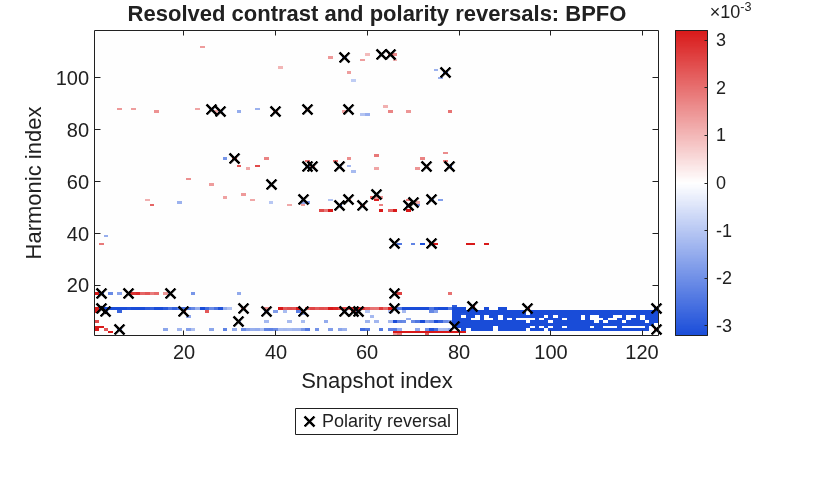

%% Visualizing resolved contrast and polarity reversals

channelTable = memberRows;

% Select one row (one run and one monitored fault family).
rowIndex = 1;
row = channelTable(rowIndex, :);

C = row.ResolvedContrast{1};     % T x H resolved contrast matrix
R = row.PolarityReversal{1};     % T x H logical reversal-event mask

[T, H] = size(C);

figure;
imagesc(1:T, 1:H, C.');
set(gca, 'YDir', 'normal');
xlabel('Snapshot index');
ylabel('Harmonic index');
title(sprintf('Resolved contrast and polarity reversals: %s', ...
    string(row.MonitoredFaultFamily)));
colormap(gca, localSignedContrastColormap());

contrastRobustPercentile = 97.5;
cmax = prctile(abs(C(:)), contrastRobustPercentile);

if cmax > 0
    clim([-cmax, cmax]);
end
colorbar;

hold on;
[tIdx, hIdx] = find(R);
plot(tIdx, hIdx, 'x', ...
    'Color', [0 0 0], ...
    'LineWidth', 1.2, ...
    'MarkerSize', 7);

legend('Polarity reversal', 'Location', 'southoutside');
hold off;

## API documentation

The class provides built-in MATLAB help and a Live Script reference documenting its public properties, constructor, dataset-building methods, and output schemas.

help ContrastPolarityChannelDatasetBuilder

 ContrastPolarityChannelDatasetBuilder Build harmonic contrast and event datasets.
 
  Constructs prognosis-channel datasets from spectral observations of
  bearing runs, with one output row per run and monitored fault family.
 
  The processing combines lifted harmonic receptive-field responses,
  sensor-local center-surround contrast, cross-sensor polarity
  agreement filtering, and temporal polarity event detection.
 
  Public methods:
    buildFromEnsemble - Process all members of a data ensemble.
    buildMemberRows   - Build channel rows for one ensemble member.
 
  Static methods:
    rawContrastNames  - Generate sensor-local contrast column names.
 
  Construction:
    obj = ContrastPolarityChannelDatasetBuilder( ...
        liftedGainFunctionsByFamily = liftedFunctions, ...
        familyNames = ["BPFO", "BPFI", "BSF", "FTF"]);
 
  Each output table row represents one bearing/run and one monitored
  fault-frequency family. The columns are:
 
 

The MATLAB `doc` command opens the corresponding documentation in the MATLAB Help Browser.

doc ContrastPolarityChannelDatasetBuilder

## Source code

The MATLAB implementation can be inspected directly using the MATLAB Editor.

edit ContrastPolarityChannelDatasetBuilder

## Test

Unit testing for the class is implemented in [`TestContrastPolarityChannelDatasetBuilder`](matlab:open('../../../tests/TestContrastPolarityChannelDatasetBuilder.m')).

results = runtests('tests/TestContrastPolarityChannelDatasetBuilder.m');

Running TestContrastPolarityChannelDatasetBuilder
........
Done TestContrastPolarityChannelDatasetBuilder
__________



SFRFsTestUtil.printTestSummary(results, 80);

Test Name                                                                        | Result
-----------------------------------------------------------------------------------------
TestContrastPolarityChannelDatasetBuilder/exposesExpectedSchemas                 | Passed
TestContrastPolarityChannelDatasetBuilder/rawContrastNamesAppendContrastSuffix   | Passed
TestContrastPolarityChannelDatasetBuilder/buildMemberRowsReturnsOneRowPerFamily  | Passed
TestContrastPolarityChannelDatasetBuilder/buildMemberRowsReturnsExpectedColumns  | Passed
TestContrastPolarityChannelDatasetBuilder/buildMemberRowsReturnsMatrixChannels   | Passed
TestContrastPolarityChannelDatasetBuilder/buildMemberRowsReturnsAgreementFloo... | Passed
TestContrastPolarityChannelDatasetBuilder/buildMemberRowsComputesBinaryEventC... | Passed
TestContrastPolarityChannelDatasetBuilder/buildMemberRowsCarriesMetadata         | Passed



## How to cite this work

If you use this toolbox in scientific work, please cite:

- Muñoz Gutiérrez, S., & Wotawa, F. (2025). *Spectral Fault Receptive Fields (SFRFs): MATLAB Toolbox*. Zenodo. [https://doi.org/10.5281/zenodo.17631784](https://doi.org/10.5281/zenodo.17631784)

For the contrast-polarity methodology, please also cite:

- Muñoz Gutiérrez, S., & Wotawa, F. (2026). *Spectral Contrast Polarity Analysis and Adaptive Sensor Fusion for Bearing Degradation Monitoring*. In *Proceedings of the 2026 IEEE International Conference on Dependable Systems and Applications (DSA 2026)*. IEEE. 

## Auxiliary functions

function cmap = localSignedContrastColormap()

n = 256;

blue = [0.100, 0.300, 0.850];
white = [1.000, 1.000, 1.000];
red = [0.850, 0.100, 0.100];

cmap = zeros(n, 3);
mid = (n + 1) / 2;

for i = 1:n
    if i <= mid
        a = (i - 1) / (mid - 1);
        cmap(i, :) = (1 - a) * blue + a * white;
    else
        a = (i - mid) / (n - mid);
        cmap(i, :) = (1 - a) * white + a * red;
    end
end

end

## References

- [1] Stan Muñoz Gutiérrez and Franz Wotawa. *Optimized Spectral Fault Receptive Fields for Diagnosis-Informed Prognosis.* In *36th International Conference on Principles of Diagnosis and Resilient Systems (DX 2025)*. Open Access Series in Informatics (OASIcs), Volume 136, pp. 9:1–9:20, Schloss Dagstuhl – Leibniz-Zentrum für Informatik (2025). DOI: 10.4230/OASIcs.DX.2025.9.

- [2] Stan Muñoz Gutiérrez and Franz Wotawa. *A Formal Framework for Spectral Fault Receptive Fields (with Examples for Bearing Health Monitoring).* Technical Report TR-SFRFs-v1.0.1, Institute of Software Engineering and Artificial Intelligence, Graz University of Technology, Graz, Austria (2026).

- [3] Stan Muñoz Gutiérrez and Franz Wotawa. *Spectral Contrast Polarity Analysis and Adaptive Sensor Fusion for Bearing Degradation Monitoring.* In *Proceedings of the 2026 IEEE International Conference on Dependable Systems and Applications (DSA 2026).* IEEE. (To appear; bibliographic details provisional.)